## Self-positioning using aircraft signals and reference sensors

Okay, let's start doing the real heavy lifting since Python couldn't handle some few millions of lines

% Load data
clear; clc;
% Helper functions' path
addpath('geodesy');
addpath('src')

% Note that for training we have results as well
training = false;

if training
    DIRECTORY_NUM = '5';
    MEASUREMENTS_DIR = sprintf('../datasets/round_1/%s/training_%s_category_1', DIRECTORY_NUM, DIRECTORY_NUM);
    RESULTS_DIR = sprintf('../datasets/round_1/%s/training_%s_category_1_result', DIRECTORY_NUM, DIRECTORY_NUM);

    % We have 2 sets: measurements and results (to compare our approach to)
    MEASUREMENTS_CSV = sprintf('training_%s_category_1.csv', DIRECTORY_NUM);
    SENSORS_CSV = 'sensors.csv';
    RESULTS_CSV = 'training_{}_category_1_result.csv';
else
    MEASUREMENTS_DIR = '../datasets/round_1';
    RESULTS_DIR = '';

    % We have 2 sets: measurements and results (to compare our approach to)
    MEASUREMENTS_CSV = 'round1_competition.csv';
    SENSORS_CSV = 'sensors.csv';
    RESULTS_CSV = '';
    
    BAD_SENSORS = [19];
end

CACHE = 'workspace.mat';

Start the parallel pool (to speed up some computations)

if isempty(gcp('nocreate'))
    parpool('local', 4, 'IdleTimeout', 120);
end

Starting parallel pool (parpool) using the 'local' profile ...
Connected to the parallel pool (number of workers: 4).


Load data (first check if it's in the cache, otherwise it's gonna take long)

if isfile(sprintf('%s/%s', MEASUREMENTS_DIR, CACHE))
    load(sprintf('%s/%s', MEASUREMENTS_DIR, CACHE), 'ddoa', 'aircraft', 'sensors');
else
    f = true;
    [aircraft, sensors] = loadData(MEASUREMENTS_DIR, MEASUREMENTS_CSV, SENSORS_CSV, f);
    ddoa = getddoa(aircraft);
    save(sprintf('%s/%s', MEASUREMENTS_DIR, CACHE), 'ddoa', 'aircraft', 'sensors');
end

% Speed of light is 299792458 m/s
c = 299792458;
ddoa.ddoam = ddoa.ddoa * 1e-9 * c;

backup_sensors = sensors; backup_aircraft = aircraft; backup_ddoa = ddoa;

% User this to restore everything
sensors = backup_sensors;
aircraft = backup_aircraft;
ddoa = backup_ddoa;

fraction = 4;
aircraft = aircraft(aircraft.id <= max(ddoa.id)/fraction,:);
ddoa = ddoa(ddoa.id <= max(ddoa.id)/fraction,:);

## Computing cartesian distances

% Computing cartesian coordinates
xyz = llh2ecef([aircraft.latitude, aircraft.longitude, aircraft.geoAltitude]);
aircraft.x = xyz(:,1);
aircraft.y = xyz(:,2);
aircraft.z = xyz(:,3);

% Let's obtain the coordinates of the aircraft measurements and also relate them
% with the average positon
center = [(quantile(aircraft.x,0.01) + quantile(aircraft.x,0.99))/2, ...
          (quantile(aircraft.y,0.01) + quantile(aircraft.y,0.99))/2, ...
          (quantile(aircraft.z,0.01) + quantile(aircraft.z,0.99))/2];
      
aircraft.x = aircraft.x - center(1);
aircraft.y = aircraft.y - center(2);
aircraft.z = aircraft.z - center(3);

% For reproducible results
rng('default');

latlims = [max(sensors.latitude), min(sensors.latitude)];
lonlims = [max(sensors.longitude), min(sensors.longitude)];

% Let's shuffle the sensors

% Let's only keep sensors that appear on the measurements
keep = zeros(size(sensors,1),1) == 1;
for ii = 1:size(sensors,1)
    if any(ddoa.s1 == sensors.serial(ii)) || any(ddoa.s2 == sensors.serial(ii))
        keep(ii) = true;
    end
end

sensors = sensors(keep,:);

% masklat = sensors_shuffled.latitude > quantile(sensors_shuffled.latitude,0.1) & sensors_shuffled.latitude < quantile(sensors_shuffled.latitude, 0.9);
% masklon = sensors_shuffled.longitude > quantile(sensors_shuffled.longitude,0.1) & sensors_shuffled.longitude < quantile(sensors_shuffled.longitude, 0.9);
% sensors_shuffled = sensors_shuffled(masklat & masklon, :);

% Let's also compute the cartesian coordinates
xyz = llh2ecef([sensors.latitude, sensors.longitude, sensors.height]);
sensors.x = xyz(:,1) - center(1);
sensors.y = xyz(:,2) - center(2);
sensors.z = xyz(:,3) - center(3);

% One of the sensors is off so we can take it out
sensors(BAD_SENSORS,:) = [];

% Remove those measurements from DDOA matrix


% We can compute the errors between the measured and expected TDOAs
maskddoa = ismember(ddoa.s1, sensors.serial, 'rows') & ismember(ddoa.s2, sensors.serial, 'rows');
ddoa = ddoa(maskddoa,:);

[~,acId] = ismember(ddoa.id, aircraft.id, 'rows');
[~,s1Id] = ismember(ddoa.s1, sensors.serial, 'rows');
[~,s2Id] = ismember(ddoa.s2, sensors.serial, 'rows');

acd = table2array(aircraft(acId,{'x', 'y', 'z'}));
s1d = table2array(sensors(s1Id,{'x', 'y', 'z'}));
s2d = table2array(sensors(s2Id,{'x', 'y', 'z'}));

% Computation of TDOAs
d1 = ecef_distance(acd, s1d);
d2 = ecef_distance(acd, s2d);

exp = d1 - d2;
ddoa.exp = exp;
ddoa.err = exp - ddoa.ddoam;

## Removing outliers

Some of the measurements are completely off and break the optimization.

Light travels almost 300.000 km per second.

A TDOA error of 30.000 km is not really possible (it's almost the earth circumference) so those measurements should be broken

maskerr = ddoa.err > quantile(ddoa.err,0.01) & ddoa.err < quantile(ddoa.err,0.99);
ddoa = ddoa(maskerr,:);

%%% Removing unnecessary aircrafts
unique_ids = unique(ddoa.id);
maskair = ismember(aircraft.id,unique_ids);
aircraft = aircraft(maskair,:);

% First we need to cleanup the aircrafts
% We can get the time and distance the aircraft moved while it was seen by the
% system
% Then we remove all the sensors that have wrong measurements
aircraft_list = unique(aircraft.aircraft);

max_dist = zeros(length(aircraft_list),1);
max_time = zeros(length(aircraft_list),1);
for ii = 1:length(aircraft_list)
    acId = aircraft_list(ii);
    aircraftPath = aircraft(aircraft.aircraft == acId, :);
    
    if height(aircraftPath) > 1
        max_dist(ii) = norm(table2array(aircraftPath(end,{'x','y','z'})) - table2array(aircraftPath(1,{'x','y','z'})))/1000;
        max_time(ii) = norm(table2array(aircraftPath(end,{'timeAtServer'})) - table2array(aircraftPath(1,{'timeAtServer'})));
    else
        max_dist(ii) = 0;
        max_time(ii) = 0;
    end
end

g = max_dist ~= 0;
good_aircraft = aircraft_list(g);

% Filter aircraft
maskair = ismember(aircraft.aircraft,good_aircraft);
aircraft = aircraft(maskair,:);

% Filter ddoa
maskddoa = ismember(ddoa.id,aircraft.id);
ddoa = ddoa(maskddoa,:);

% We can obtain the ids of the sensors that are 'good'
% good = unique([pairs.s1(mask); pairs.s2(mask)]);
% sensors_shuffled = sensors_shuffled(ismember(sensors_shuffled.serial,good),:);
% ddoa = ddoa(ismember(ddoa.s1,good) & ismember(ddoa.s2,good),:);

## Optimization approaches (with offset)

In this one, we will use all sensors but one and optimize the position (imitating a user)

We'll start by computing all the offsets

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%% Linear least squares    
% We start with the C matrix
C = zeros(height(ddoa), height(sensors));
for index = 1:height(sensors)
    s = sensors.serial(index);
    mask_positive = ddoa.s1 == s;
    mask_negative = ddoa.s2 == s;
    
    C(mask_positive, index) = 1;
    C(mask_negative, index) = -1;
end

% Now the d vector
d = -ddoa.err;

% We set the lower and upper bounds
sigma = std(ddoa.err);
% lb = [-1e-6; -5*sigma.*ones(height(sensors_shuffled)-1,1)];
% ub = [1e-6; 5*sigma.*ones(height(sensors_shuffled)-1,1)];
lb = [-1e-6;-inf.*ones(height(sensors)-1,1)];
ub = [1e-6; inf.*ones(height(sensors)-1,1)];

offsets = lsqlin(C,d,[],[],[],[],lb,ub);


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


sensors.offsets = offsets;

% Optimization by sensor
result = zeros(height(sensors),4); % x, y, z & offset

% Some options for the algorithm
options = optimoptions('fminunc','Display','off','Algorithm','trust-region',...
                       'SpecifyObjectiveGradient',true,'UseParallel',true,'MaxIterations',4000,...
                       'MaxFunctionEvaluations', 30000, 'StepTolerance',1e-15, 'OptimalityTolerance',1e-15);

num_ref = 5; % Number of reference sensors to use 
for ii = 1:height(sensors)
    %% Data preparation
    sensor = sensors(ii,:);

    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    %% Computing initial point
    mask = (ddoa.s1 == sensor.serial) | (ddoa.s2 == sensor.serial);
    
    % Obtaining positions of the most common sensors
    ddoa_sensor_count = grpstats(ddoa(mask,:),{'s1','s2'});
    ddoa_sensor_count = sortrows(ddoa_sensor_count,'GroupCount','descend');
    Ng = min([height(ddoa_sensor_count), num_ref]);
    if Ng < num_ref
        warning('Not enough reference sensors');
        fprintf('Number of sensors that will be used: %d',Ng);
    end
    
    indices = zeros(Ng,1);
    for jj = 1:Ng
        if ddoa_sensor_count.s1(jj) == sensor.serial
            indices(jj) = find(sensors.serial == ddoa_sensor_count.s2(jj));
        else
            indices(jj) = find(sensors.serial == ddoa_sensor_count.s1(jj));
        end
    end
    ground = sensors(indices,:);
    
    % We need the mean positions
    unique_id = unique(ddoa.id(mask));
    [~,idx,~] = intersect(aircraft.id,unique_id);
    
    p0.x = mean(aircraft.x(idx));
    p0.y = mean(aircraft.y(idx));
    p0.z = mean(aircraft.z(idx));
    
    % Let's filter the data
    mask_s = ismember(ddoa.s1, sensor.serial, 'rows') | ismember(ddoa.s2, sensor.serial, 'rows');
    mask_g = ismember(ddoa.s1, ground.serial, 'rows') | ismember(ddoa.s2, ground.serial, 'rows');
    mask = mask_s & mask_g;

    data = ddoa(mask,:);
    
    %% Now that we have the offsets let's start with the real optimization
    fun = @(x) minimizeroffset(x(1), x(2), x(3), x(4), sensor.serial, aircraft, data, ground(:,{'x','y','z','offsets','serial'}));
    
                    
    % Here starts the fun
    x0 = [p0.x; p0.y; p0.z; 2*5*sigma*rand(1)-5*sigma];
    tic;
    try
        [position,fval,flag] = fminunc(fun,x0,options);
    catch
        warning('Could not optimize position');
        fval = 0;
    end
    toc;
    if fval ~= 0
        result(ii,:) = position';
    else
        result(ii,:) = [0.0 0.0 0.0 0.0];
    end
end

Elapsed time is 9.966075 seconds.
Elapsed time is 21.785884 seconds.
Elapsed time is 36.561465 seconds.
Elapsed time is 13.385671 seconds.
Elapsed time is 10.560657 seconds.
Elapsed time is 22.214513 seconds.
Elapsed time is 36.860503 seconds.
Elapsed time is 23.463714 seconds.
Elapsed time is 21.064458 seconds.


Number of sensors that will be used: 2

Elapsed time is 27.551270 seconds.


Number of sensors that will be used: 4

Elapsed time is 16.338000 seconds.


Number of sensors that will be used: 4

Elapsed time is 7.270446 seconds.
Elapsed time is 18.758569 seconds.
Elapsed time is 28.076724 seconds.
Elapsed time is 14.733212 seconds.
Elapsed time is 55.534992 seconds.
Elapsed time is 7.015465 seconds.


Number of sensors that will be used: 3

Elapsed time is 6.982212 seconds.
Elapsed time is 27.213331 seconds.
Elapsed time is 51.748607 seconds.
Elapsed time is 10.055193 seconds.
Elapsed time is 19.777814 seconds.
Elapsed time is 22.517061 seconds.
Elapsed time is 23.250548 seconds.
Elapsed time is 26.059845 seconds.
Elapsed time is 6.003127 seconds.
Elapsed time is 8.805812 seconds.
Elapsed time is 29.750356 seconds.


Number of sensors that will be used: 4

Elapsed time is 35.747070 seconds.
Elapsed time is 9.382948 seconds.


Number of sensors that will be used: 4

Elapsed time is 17.789370 seconds.


Number of sensors that will be used: 4

Elapsed time is 20.181889 seconds.


Number of sensors that will be used: 4

Elapsed time is 68.437858 seconds.
Elapsed time is 13.059454 seconds.
Elapsed time is 60.184483 seconds.
Elapsed time is 66.596969 seconds.
Elapsed time is 20.033826 seconds.


% Let's calculate errors
unknownsens = sensors;
valid = find(~all(result==0,2));
invalid = find(all(result==0,2));
resval = result(valid,1:3); senval = table2array(unknownsens(valid,{'x','y','z'}));

errors = resval(:,1:3) - senval;
errnrm = sqrt(sum(errors.^2,2));

rmse = sqrt(median(errnrm.^2))

rmse = 100.3853

% Compute the 2D distance
unknownllh = ecef2llh(resval(:,1:3) + center);
realposllh = table2array(sensors(:, {'latitude','longitude','height'}));

dist = havdist(unknownllh, realposllh(valid,:));
[distno,id] = rmoutliers(dist);
rmse_2d = rms(distno)

rmse_2d = 30.2770

rmse_2d_normal = sqrt(median(dist.^2))

rmse_2d_normal = 29.2545

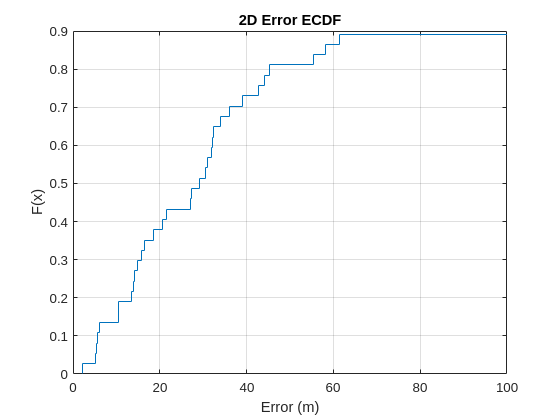

figure();
ecdf(dist); grid on;
xlabel('Error (m)');
title('2D Error ECDF');
xlim([0,100]);

## Optimization (without offset)

In this part we will optimize without taking into account the offsets of sensors

% Optimization by sensor
result = zeros(height(sensors),3); % x, y, z & offset

% Some options for the algorithm
options = optimoptions('fminunc','Display','off','Algorithm','quasi-newton',...
                       'SpecifyObjectiveGradient',true,'UseParallel',true,'MaxIterations',1000,...
                       'MaxFunctionEvaluations', 300000, 'StepTolerance',1e-12, 'OptimalityTolerance',1e-12);

num_ref = inf; % Number of reference sensors to use 
for ii = 1:height(sensors)
    %% Data preparation
    sensor = sensors(ii,:);

    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    %% Computing initial point
    mask = (ddoa.s1 == sensor.serial) | (ddoa.s2 == sensor.serial);
    
    % Obtaining positions of the most common sensors
    ddoa_sensor_count = grpstats(ddoa(mask,:),{'s1','s2'});
    ddoa_sensor_count = sortrows(ddoa_sensor_count,'GroupCount','descend');
    Ng = min(height(ddoa_sensor_count), num_ref);
    if height(ddoa_sensor_count) < num_ref
        warning('Not enough reference sensors');
    end
    
    indices = zeros(Ng,1);
    for jj = 1:Ng
        if ddoa_sensor_count.s1(jj) == sensor.serial
            indices(jj) = find(sensors.serial == ddoa_sensor_count.s2(jj));
        else
            indices(jj) = find(sensors.serial == ddoa_sensor_count.s1(jj));
        end
    end
    ground = sensors(indices,:);
    
    % We need the mean positions
    unique_id = unique(ddoa.id(mask));
    [~,idx,~] = intersect(aircraft.id,unique_id);
    
    p0.x = mean(aircraft.x(idx));
    p0.y = mean(aircraft.y(idx));
    p0.z = mean(aircraft.z(idx));
    
    % Let's filter the data
    mask_s = ismember(ddoa.s1, sensor.serial, 'rows') | ismember(ddoa.s2, sensor.serial, 'rows');
    mask_g = ismember(ddoa.s1, ground.serial, 'rows') | ismember(ddoa.s2, ground.serial, 'rows');
    mask = mask_s & mask_g;

    data = ddoa(mask,:);

    %% Now that we have the offsets let's start with the real optimization
    fun = @(x) minimizer2(x(1), x(2), x(3), sensor.serial, aircraft, data, ground(:,{'x','y','z','serial'}));
    
                    
    % Here starts the fun
    x0 = [p0.x; p0.y; p0.z];
    tic;
    [position,fval,flag] = fminunc(fun,x0,options);
    toc;
    if fval ~= 0
        result(ii,:) = position';
    else
        result(ii,:) = [0.0 0.0 0.0 0.0];
    end
end

Elapsed time is 1.219356 seconds.


Elapsed time is 1.073977 seconds.


Elapsed time is 0.798265 seconds.


Elapsed time is 1.008581 seconds.


Elapsed time is 0.720236 seconds.


Elapsed time is 1.341736 seconds.


Elapsed time is 1.108036 seconds.


Elapsed time is 1.189822 seconds.


Elapsed time is 1.391945 seconds.


Elapsed time is 1.927765 seconds.


Elapsed time is 1.244883 seconds.


Elapsed time is 0.821932 seconds.


Elapsed time is 2.156567 seconds.


Elapsed time is 1.209604 seconds.


Elapsed time is 3.148849 seconds.


Elapsed time is 1.908128 seconds.


Elapsed time is 2.005325 seconds.


Elapsed time is 1.295200 seconds.


Elapsed time is 1.032580 seconds.


Elapsed time is 1.988466 seconds.


Elapsed time is 1.807537 seconds.


Elapsed time is 1.007387 seconds.


Elapsed time is 1.861899 seconds.


Elapsed time is 1.665758 seconds.


Elapsed time is 1.706908 seconds.


Elapsed time is 0.742916 seconds.


Elapsed time is 1.422336 seconds.


Elapsed time is 1.590241 seconds.


Elapsed time is 1.446254 seconds.


Elapsed time is 1.176633 seconds.


Elapsed time is 2.641882 seconds.


Elapsed time is 1.914660 seconds.


Elapsed time is 2.239530 seconds.


Elapsed time is 1.705763 seconds.


Elapsed time is 1.705535 seconds.


Elapsed time is 1.271945 seconds.


Elapsed time is 1.458119 seconds.


% Let's calculate errors
unknownsens = sensors;
valid = find(~all(result==0,2));
invalid = find(all(result==0,2));
resval = result(valid,1:3); senval = table2array(unknownsens(valid,{'x','y','z'}));

errors = resval(:,1:3) - senval;
errnrm = sqrt(sum(errors.^2,2));

rmse = sqrt(median(errnrm.^2))

rmse = 110.9679

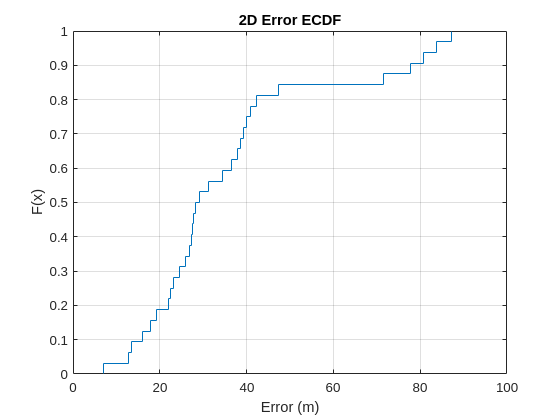

% Compute the 2D distance
unknownllh = ecef2llh(resval(:,1:3) + center);
realposllh = table2array(sensors(:, {'latitude','longitude','height'}));

dist = havdist(unknownllh, realposllh(valid,:));
[distno,id] = rmoutliers(dist);
rmse_2d = rms(distno);
figure();
ecdf(distno); grid on;
xlabel('Error (m)');
title('2D Error ECDF');

## Comparing both approaches

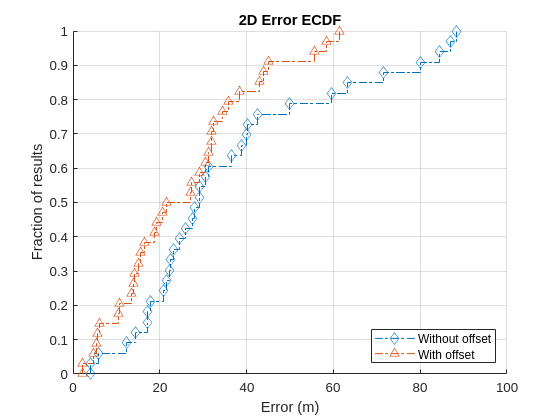

load('results/min_v4_combined.mat');

% With no offset
% Compute the 2D distance
unknownllhno = ecef2llh(resultno(:,1:3) + center);
realposllhno = table2array(sensors(:, {'latitude','longitude','height'}));

distno = havdist(unknownllhno, realposllhno);
[distrmno,idno] = rmoutliers(distno);
rmse_2dno = rms(distrmno);

% With offset
% Compute the 2D distance
unknownllh = ecef2llh(result(:,1:3) + center);
realposllh = table2array(sensors(:, {'latitude','longitude','height'}));

dist = havdist(unknownllh, realposllh);
[distrm,id] = rmoutliers(dist);
rmse_2d = rms(distrm);

% Plotting
figure(); hold on;
[fno, yno] = ecdf(distrmno); grid on;
stairs(yno,fno,'d-.');
[f,y] = ecdf(distrm);
stairs(y,f,'^-.')
xlabel('Error (m)');
ylabel('Fraction of results');
title('2D Error ECDF');
legend('Without offset', 'With offset','Location',"southeast");
    xlim([0,100]);

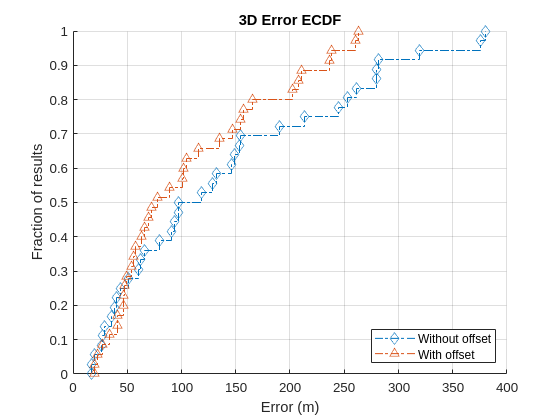

load('results/min_v4_combined.mat');

% With no offset
% Compute the 2D distance
unknownllhno = ecef2llh(resultno(:,1:3) + center);
realposllhno = table2array(sensors(:, {'latitude','longitude','height'}));

dist3dno = dist3fromllh(unknownllhno, realposllhno);
[dist3drmno,idno] = rmoutliers(dist3dno);
rmse_2dno = rms(dist3drmno);

% With offset
% Compute the 2D distance
unknownllh = ecef2llh(result(:,1:3) + center);
realposllh = table2array(sensors(:, {'latitude','longitude','height'}));

dist3d = dist3fromllh(unknownllh, realposllh);
[dist3drm,id] = rmoutliers(dist3d);
rmse_2d = rms(dist3drm);

% Plotting
figure(); hold on;
[fno,yno] = ecdf(dist3drmno); grid on;
stairs(yno,fno,'d-.');
[f,y] = ecdf(dist3drm);
stairs(y,f,'^-.')
xlabel('Error (m)');
ylabel('Fraction of results');
title('3D Error ECDF');
legend('Without offset', 'With offset','Location',"southeast");

## The Map (to visualize everything)

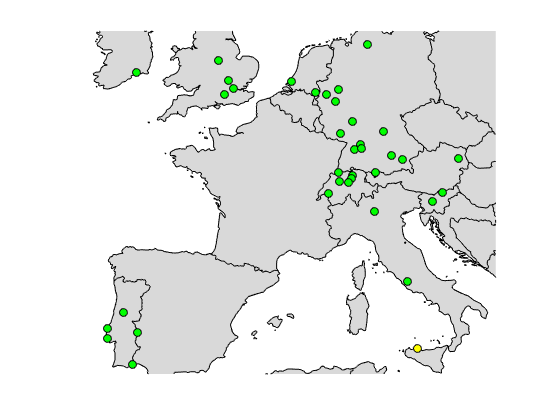

id = zeros(38,1) == 1; id(19) = true;
good = sensors(~id,:);
bad = sensors(id,:);

% prepare the map
figure
ax = worldmap([20 70],[-30 40]);
hold on
setm(ax, 'MapProjection',"mercator", 'Frame',"off", 'Grid',"off")
%% zoom in
ax.XLim = [-1.7846e+06 1.5681e+06];
ax.YLim = [4.3808e+06 7.1748e+06];
% plot borders / lands
geoshow(ax, 'shapefiles/CNTR_RG_10M_2016_4326.shp', 'FaceColor',[0.85 0.85 0.85]);
% plot good sensor locations (green dots)
scatterm(good.latitude, good.longitude, [], 'green', 'filled','MarkerEdgeColor',[0 0 0]);
% plot bad sensor locations (yellow dots)
scatterm(bad.latitude, bad.longitude, [], 'yellow', 'filled','MarkerEdgeColor',[0 0 0]);

% plot result locations (red circles)
scatterm(unknownllh(:,1), unknownllh(:,2), [], 'red');

Reference to a cleared variable unknownllh.

% calculate the directions
% vec = [unknownllh(:,1) - realposllh(:,1), unknownllh(:,2) - realposllh(:,2)];
% vec = vec ./ vecnorm(vec')';
% quiverm(realposllh(:,1), realposllh(:,2), vec(:,1), vec(:,2), 0.2);
hold off
